Produce plots of the following in Matlab.

- 
$$\sin \left(\textrm{kx}\right)$$


- 
$$x^2$$


- $-a$ when $c<x<d$, otherwise $0$, where $a$ is an arbitrary number

clc
clear
x = linspace(-10, 10, 1000);

%% Function #1
k = 10;
y1 = sin(k * x);

% Plot and decorate
subplot(2,2,1);
plot(x, y1, "r");
title("Function #1");
xlabel("x");
ylabel("y");
legend("y = sin(" + k + "x)");

%% Function #2
y2 = x.^2;

% Plot and decorate
subplot(2,2,2);
plot(x, y2, "b");
title("Function #2");
xlabel("x");
ylabel("y");
legend("y = x^2");

%% Function #3
a=rand(1);
c=rand(1);
d=rand(1)+1;

y3_1 = zeros(size(x));
y3_2 = zeros(size(x));

y3_1((c < x) & (x < d)) = -a;
y3_2((c > x) | (d > x)) = 0;

y3 = y3_1 + y3_2

y3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


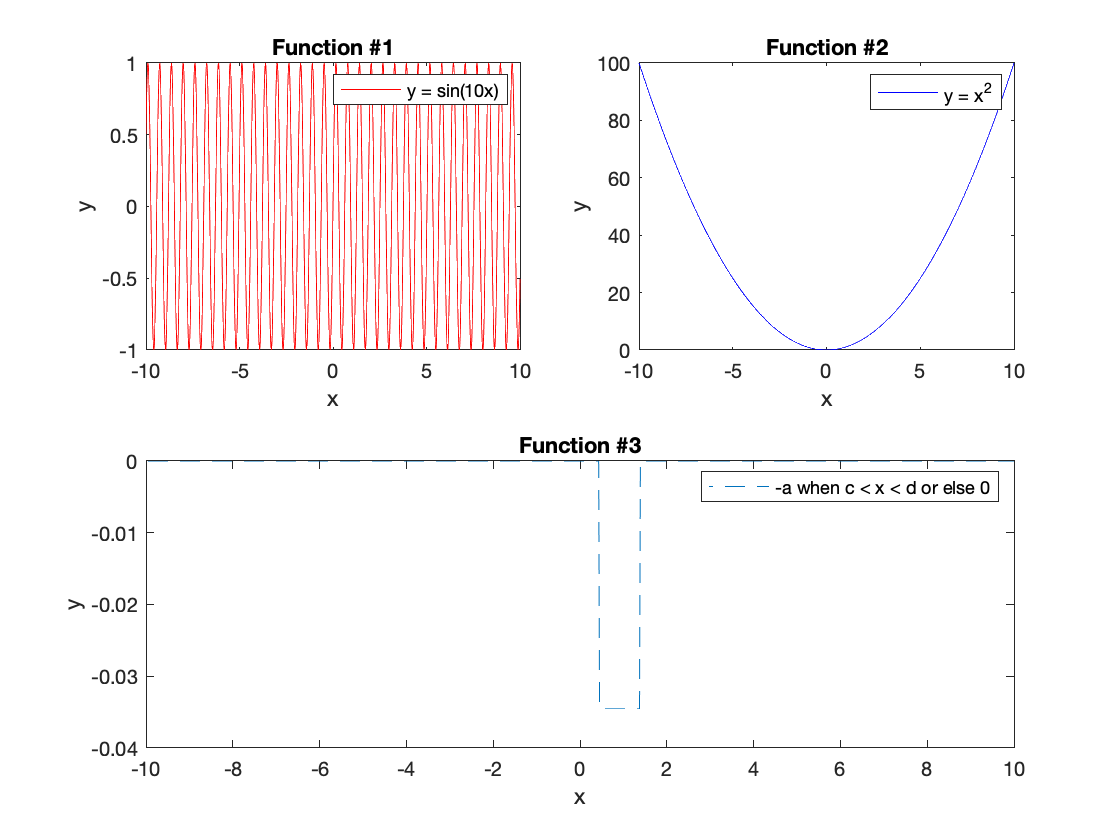


subplot(2,2,[3, 4]);
plot(x, y3, "--")
title("Function #3");
xlabel("x");
ylabel("y");
legend("-a when c < x < d or else 0");